### **Figure 5: Simulation pepline**

**Contents**

**Figure 5e**

**Figure 5f**

**Figure 5g**

**Figure 5h**

**Figure 5i**

**Functions**

**Figure 5a Resource competition model on iron competition**

Define the initial conditions and parameters

addpath('./functions/')
t_end = 1400000;
h=0.02;
num_strain = 20;     % theta in the model
num_sid = 10;        % i in the model
Riron_supply = 30;  % iron in supply
barcode_syn = zeros(num_strain); % barcode for synthetase

% Initialize arrays to store the results
num_iteration=1000;

m_steady=zeros(num_iteration,num_strain);
g_steady=zeros(num_iteration,num_strain);
R_com_steady=zeros(num_iteration,num_sid);
R_sid_steady=zeros(num_iteration,num_sid);
R_iron_steady=zeros(num_iteration,num_sid);
a_record = zeros(num_iteration,num_strain);
m0_record = zeros(num_iteration,num_strain);
barcode_syn_record=zeros(num_sid,num_strain,num_iteration);
barcode_rec_record=zeros(num_sid,num_strain,num_iteration);

read rec_num distribution

rng(42)
rec_distr = table2array(readtable('rec_num.xlsx'));
hist_rec = histcounts(rec_distr);
probabilities = hist_rec;

Use Euler's method to solve the ODE numerically

parfor k = 1:num_iteration
    rng(k) % set random seed
    m0=rand(1,num_strain); % initial mass
    a_rand = rand(1,num_strain);
    a = [a_rand;1-a_rand]; % growth strategy
    barcode_syn=zeros(num_sid,num_strain); % barcode for synthetase
    for col = 1:num_strain
        row = randi([1, num_sid]); % 随机选择1到10之间的一个整数
        barcode_syn(row, col) = 1;
    end
    barcode_rec=zeros(num_sid,num_strain);
    for i = 1:num_strain
        rec_self = find(barcode_syn(:,i));
        rec_samples = randsample(2:num_sid, 1, true, probabilities(2:num_sid)); % 通过分布确定每个菌株有几个receptor
        rec_have = randsample([1:rec_self-1,rec_self+1:num_sid],rec_samples-1); % 确定有哪几个receptor
%         rec_rand = rand(1,rec_samples); 
%         rec_weight = rec_rand./sum(rec_rand); % weight of each receptor
%         barcode_rec([rec_self rec_have],i) = rec_weight;
        rec_rand = rand(1,rec_samples-1);
        rec_weight = rec_rand./sum(rec_rand).*0.8; % weight of each receptor
        barcode_rec([rec_self rec_have],i) = [0.2 rec_weight];
    end
    

    [t_values,m_values,g_values,j_values,Rcom_values,Rsid_values,Riron_values,dmdt]=...
        simulation_community_interaction4(num_strain,num_sid,a,m0,Riron_supply,t_end,h,barcode_syn,barcode_rec);
    % steady state
    m_steady(k,:)=m_values(end,:);
    g_steady(k,:)=g_values(end,:);
    R_com_steady(k,:)=Rcom_values(end,:);
    R_sid_steady(k,:)=Rsid_values(end,:);
    R_iron_steady(k,:)=Riron_values(end,:);
    % parameters
    a_record(k,:)=a(1,:);
    m0_record(k,:)=m0;
    barcode_rec_record(:,:,k)=barcode_rec;
    barcode_syn_record(:,:,k)=barcode_syn;
%     % dynamics
%     m_dynamics_all(:,:,k) = m_values;
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to the parallel pool (number of workers: 8).


**Figure5b Simulation of a Community Composed Exclusively of a Single Strategic Type: single-receptor producers, multi-receptor producers, and non-producers**

the loading data is the file save in Figure 5a

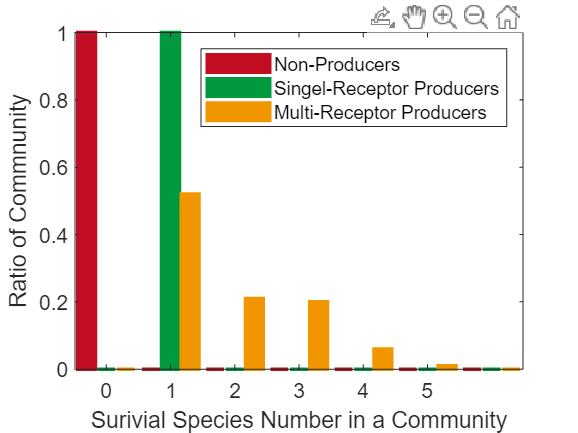

% plot all result in a same figure: strain number
max_coexist = 6;
x_all = [];
load('./result_clusterserver/ecology_figure1_cheating_3.mat') % load partial cheater result
x=tabulate(survival_matrix);
x_new = zeros(max_coexist+1,2);
x_new(:,1)=0:max_coexist;
x_new(x(:,1)+1,2)=x(:,2);
x_all=[x_all;x_new];
load('./result_clusterserver/ecology_figure1_pure_3.mat') % load partial cheater result
x=tabulate(survival_matrix);
x_new = zeros(max_coexist+1,2);
x_new(:,1)=0:max_coexist;
x_new(x(:,1)+1,2)=x(:,2);
x_all=[x_all,x_new(:,2)];
load('./result_clusterserver/ecology_figure1_partial_3.mat') % load partial cheater result
x=tabulate(survival_matrix);
x_new = zeros(max_coexist+1,2);
x_new(:,1)=0:max_coexist;
x_new(x(:,1)+1,2)=x(:,2);
x_all=[x_all,x_new(:,2)];


figure
numBars = size(x_all, 2) - 1;  
numGroups = size(x_all, 1);
groupSpacing = 0.25;
positions = repmat(1:numGroups, numBars, 1).' + (((1:numBars) - (numBars+1)/2) * groupSpacing);
hBar = bar(positions-1, x_all(:,2:end)./100,'BarWidth',5);
legend('Non-Producers','Singel-Receptor Producers', 'Multi-Receptor Producers')
hBar(1).FaceColor=[195,13,35]./255;%'red';
hBar(1).EdgeColor=[195,13,35]./255;
hBar(1).LineWidth=1.7;
hBar(2).FaceColor=[0,153,62]./255;%'green';
hBar(2).EdgeColor=[0,153,62]./255;
hBar(2).LineWidth=1.7;
hBar(3).FaceColor=[242,150,0]./255;%'yellow';
hBar(3).EdgeColor=[242,150,0]./255;
hBar(3).LineWidth=1.7;
xlabel('Surivial Species Number in a Community')
ylabel('Ratio of Commnunity')
xticks([0:5])

**Figure 5c Simulation of an invasion event within a community**

Define the initial conditions and parameters

addpath('tools/parsave/')
t_end = 20000;
h=0.02;
num_strain = 20;     % theta in the model
num_sid = 10;        % i in the model
Riron_supply = 30;  % iron in supply

% Initialize arrays to store the results
num_iteration=1;
num_repeat = 2;

m_steady=zeros(num_iteration,num_strain);
g_steady=zeros(num_iteration,num_strain);
R_com_steady=zeros(num_iteration,num_sid);
R_sid_steady=zeros(num_iteration,num_sid);
R_iron_steady=zeros(num_iteration,num_sid);

m_steady2=zeros(num_iteration,num_strain);
g_steady2=zeros(num_iteration,num_strain);
R_com_steady2=zeros(num_iteration,num_sid);
R_sid_steady2=zeros(num_iteration,num_sid);
R_iron_steady2=zeros(num_iteration,num_sid);

a_record = zeros(num_iteration,num_strain);
m0_record = zeros(num_iteration,num_strain);
barcode_syn_record=zeros(num_sid,num_strain);
barcode_rec_record=zeros(num_sid,num_strain);

m_dynamics_all = zeros(t_end*2,num_strain);
% splitPoints_all = zeros(num_iteration,2);

% read communities
cheating = load('result_clusterserver/ecology_figure1_cheating_4_10000.mat'...
    ,'barcode_syn_record','barcode_rec_record','a_record','m0_record');
pure = load('result_clusterserver/ecology_figure1_pure_4_10000.mat'...
    ,'barcode_syn_record','barcode_rec_record','a_record','m0_record');
partial = load('result_clusterserver/ecology_figure1_partial_4_10000.mat'...
    ,'barcode_syn_record','barcode_rec_record','a_record','m0_record');
cheating.name = 'cheating';
pure.name = 'pure';
partial.name = 'partial';
strategy_name = {pure,partial,cheating};

Use Euler's method to solve the ODE numerically

parpool(4)
for i = 3 % iterate invader
    for j = 1:3 % iterate community, 1: pure, 2: partial, 3: mix
        if j <= 2
            folder_name = [strategy_name{i}.name '_invade_' strategy_name{j}.name];
            mkdir(folder_name);
        else
            folder_name = [strategy_name{i}.name '_invade_mix' ];
            mkdir(folder_name);
        end
        parfor k =1:num_repeat
            if j<=2 % community as pure or partial
                % concat barcode of different strategies
                [barcode_syn,barcode_rec,a,m0,community_name_temp] = generate_mix_invasion(k,num_strain,strategy_name{j},strategy_name{i});
            else
                [barcode_syn,barcode_rec,a,m0,community_name_temp,splitPoints] = generate_mix_invasion_2component(k,num_strain,pure,partial,strategy_name{i});
            end
            % invader
            m_invasion = m0(end);
            m0(end) = 0;
            a(:,end) = 1.5*a(:,end);

            % first round
            [t_values,m_values,g_values,j_values,Rcom_values,Rsid_values,Riron_values,dmdt]=...
                simulation_community_interaction4_breakpoint(num_strain,num_sid,a,m0,Riron_supply,t_end,h,barcode_syn,barcode_rec);
            % second round: invasion
            [t_values2,m_values2,g_values2,j_values2,Rcom_values2,Rsid_values2,Riron_values2,dmdt2]=...
                simulation_community_interaction4_breakpoint(num_strain,num_sid,a,[m_values(end,1:end-1) m_invasion],Riron_supply,t_end,h,barcode_syn,barcode_rec...
                ,g_values(end,:),j_values(end,:),Rcom_values(end,:),Rsid_values(end,:),Riron_values(end,:));

            % steady state
            m_steady=m_values(end,:);
            g_steady=g_values(end,:);
            R_com_steady=Rcom_values(end,:);
            R_sid_steady=Rsid_values(end,:);
            R_iron_steady=Riron_values(end,:);

            m_steady2=m_values2(end,:);
            g_steady2=g_values2(end,:);
            R_com_steady2=Rcom_values2(end,:);
            R_sid_steady2=Rsid_values2(end,:);
            R_iron_steady2=Riron_values2(end,:);

            % parameters
            a_record=a(1,:);
            m0_record1=m0;
            m0_record2=[m_values(end,1:end-1) m_invasion];
            barcode_rec_record=barcode_rec;
            barcode_syn_record=barcode_syn;
            %     splitPoints_all(k,:)=splitPoints;
            % dynamics
            m_dynamics_all = [m_values; m_values2];
            if j<=2
                parsave([folder_name '/ecology_figure3_invasion_1_' folder_name '_' num2str(k) '.mat'],m_steady,m_steady2,...
                    a_record,m0_record1,m0_record2,barcode_rec_record,barcode_syn_record,m_dynamics_all)
            else
                parsave([folder_name '/ecology_figure3_invasion_1_' folder_name '_' num2str(k) '.mat'],m_steady,m_steady2,...
                    a_record,m0_record1,m0_record2,barcode_rec_record,barcode_syn_record,m_dynamics_all,splitPoints)
            end
            % J Weijs (2024). parsave (https://www.mathworks.com/matlabcentral/fileexchange/57933-parsave), MATLAB Central File Exchange. Retrieved August 11, 2024.
        end
        i,j
        toc
    end
end
toc

**Figure5d The probability of invader wiping original community out**

tic
invader_name = {'pure','partial','cheating'};
community_name = {'pure','partial','mix'};
invasion_ratio_all = zeros(3);
invasion_ratio_all2 = zeros(3);
wipeout_ratio_all  = zeros(3);
all_extinction_ratio_all = zeros(3);
community_diff_all = zeros(3);
diversity_loss_all = zeros(3);
invasion_success_all = cell(3);
invasion_success2_all = cell(3);
survival_matrix_all = cell(3);
survival_matrix2_all = cell(3);
m_steady_all = cell(3);
m_steady2_all = cell(3);
max_biomass_all = cell(3);

parpool(30)
for j = 1:3 % iterate invaders
    for k = 1:3 % iterate community
        num_repeat = 2;  
        num_strain = 20;
        num_sid = 10;
        m_steady2 = zeros(num_repeat,num_strain); % steady biomass of each strain after invasion
        m_steady = zeros(num_repeat,num_strain); % steady biomass of each strain before invasion
        barcode_syn_record = zeros(num_sid,num_strain,num_repeat);
        barcode_rec_record = zeros(num_sid,num_strain,num_repeat);
        invasion_success2 = zeros(num_repeat,1);
        max_biomass = zeros(num_repeat,num_strain);
        parfor i =1:num_repeat
            temp_data = load([invader_name{j} '_invade_' community_name{k} '/ecology_figure3_invasion_1_' ...
                invader_name{j} '_invade_' community_name{k} '_' num2str(i) '.mat'],...
                'm_steady2','m_steady','barcode_syn_record','barcode_rec_record','m_dynamics_all','m0_record2');
            m_steady2(i,:) = temp_data.m_steady2;
            m_steady(i,:) = temp_data.m_steady;
            max_biomass(i,:) = max(temp_data.m_dynamics_all,[],1)
            barcode_syn_record(:,:,i) = temp_data.barcode_syn_record;
            barcode_rec_record(:,:,i) = temp_data.barcode_rec_record;
            if any(temp_data.m_dynamics_all(:,end)>10) % any(temp_data.m_dynamics_all(:,end)>10*m0_record2(end))
                invasion_success2(i) = 1; % the definition of invasion success here: the biomass of invader surpass 10 at any moment
            end
        end

        % community diversity
        survival_matrix = sum(m_steady>1,2);
        survival_matrix2 = sum(m_steady2>1,2);

        % whether the community extinct before invasion
        not_extinct = survival_matrix>0; % the community not extinct before invasion

        % successfully invasion
        invasion_success = m_steady2(:,end)>1;
        invasion_ratio = sum(invasion_success(not_extinct))./length(invasion_success(not_extinct));
        invasion_ratio2 = sum(invasion_success2(not_extinct))./length(invasion_success2(not_extinct));

        % wipe out the original strains
        wipeout_success = sum(m_steady2(:,1:end-1)>1,2)==0;
        wipeout_ratio = sum(wipeout_success(not_extinct))./length(wipeout_success(not_extinct));

        % all extinction ratio
        all_extinction = sum(m_steady2(:,1:end)>1,2)==0;
        all_extinction_ratio = sum(all_extinction(not_extinct))./length(all_extinction(not_extinct));

        % difference of community vectors
        community_diff_all = sum(abs(double(m_steady2>1) - double(m_steady>1)),2)
        community_diff = mean(community_diff_all(not_extinct));

        % loss of diversity in the successfully invasion samples
        diversity_loss_all = survival_matrix - survival_matrix2;
        diversity_loss = sum(diversity_loss_all(not_extinct))...
            ./length(diversity_loss_all(not_extinct));

        invasion_ratio_all(j,k) = invasion_ratio;
        invasion_ratio_all2(j,k) = invasion_ratio2;
        wipeout_ratio_all(j,k) = wipeout_ratio;
        all_extinction_ratio_all(j,k) = all_extinction_ratio;
        community_diff_all(j,k) = community_diff;
        diversity_loss_all(j,k) = diversity_loss;
        invasion_success_all{j,k} = invasion_success;
        invasion_success2_all{j,k} = invasion_success2;
        survival_matrix_all{j,k} = survival_matrix;
        survival_matrix2_all{j,k} = survival_matrix2;
        m_steady_all{j,k} = m_steady;
        m_steady2_all{j,k} = m_steady2;
        max_biomass_all{j,k} = max_biomass;
    end
end
toc

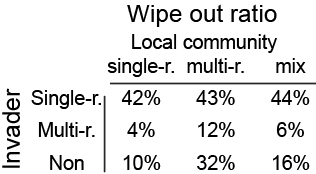

**Figure5e The probability of a single-receptor producer successfully invading a community consisting of multi-receptor producers**

clear
clc
num_repeat = 5000;
num_strain = 20;
num_sid = 10;
m_steady2 = zeros(num_repeat,num_strain);
m_steady = zeros(num_repeat,num_strain);
m0_record1 = zeros(num_repeat,num_strain);
m0_record2 = zeros(num_repeat,num_strain);
a_record = zeros(num_repeat,num_strain);
barcode_syn_record = zeros(num_sid,num_strain,num_repeat);
barcode_rec_record = zeros(num_sid,num_strain,num_repeat);
for i =1:num_repeat
    temp_data = load(['pure_invade_partial/ecology_figure3_invasion_1_pure_invade_partial_' num2str(i) '.mat'],...
        'm_steady2','m_steady','barcode_syn_record','barcode_rec_record','m0_record2','m0_record1','a_record');
    m_steady2(i,:) = temp_data.m_steady2;
    m_steady(i,:) = temp_data.m_steady;
    m0_record1(i,:) = temp_data.m0_record1;
    m0_record2(i,:) = temp_data.m0_record2;
    a_record(i,:) = temp_data.a_record;
    barcode_syn_record(:,:,i) = temp_data.barcode_syn_record;
    barcode_rec_record(:,:,i) = temp_data.barcode_rec_record;
end

invasion probability for different iron interactions

not_extinct = sum(survial_species,2)>0;
has_cooperator = zeros(num_repeat,1); % community has at least one cooperator
has_partial_cheater = zeros(num_repeat,1); % community has as least one partial cheater
for i = 1:num_repeat
    if any(correct_syn(i,survial_species(i,:))>0&correct_rec(i,survial_species(i,:))>0)
        has_cooperator(i)=1;
    else
        has_cooperator(i)=0;
    end
    if any(correct_syn(i,survial_species(i,:))==0&correct_rec(i,survial_species(i,:))>0)
        has_partial_cheater(i)=1;
    else
        has_partial_cheater(i)=0;
    end
end
sum(has_cooperator)
sum(has_partial_cheater)

% no partial cheater, no cooperator
no_partial_cheater_no_cooperator = ~has_partial_cheater&~has_cooperator&not_extinct;
sum(no_partial_cheater_no_cooperator)
sum(invasion_success(no_partial_cheater_no_cooperator))
no_partial_cheater_no_cooperator_ratio = sum(invasion_success(no_partial_cheater_no_cooperator))./sum(no_partial_cheater_no_cooperator)

% no partial cheater, has cooperator
no_partial_cheater_has_cooperator = ~has_partial_cheater&has_cooperator&not_extinct;
sum(no_partial_cheater_has_cooperator)
sum(invasion_success(no_partial_cheater_has_cooperator))
no_partial_cheater_has_cooperator_ratio = sum(invasion_success(no_partial_cheater_has_cooperator))./sum(no_partial_cheater_has_cooperator)

% has partial cheater, no cooperator
has_partial_cheater_no_cooperator = has_partial_cheater&~has_cooperator&not_extinct;
sum(has_partial_cheater_no_cooperator)
sum(invasion_success(has_partial_cheater_no_cooperator))
has_partial_cheater_no_cooperator_ratio = sum(invasion_success(has_partial_cheater_no_cooperator))./sum(has_partial_cheater_no_cooperator)

% has partial cheater, has cooperator
has_partial_cheater_has_cooperator = has_partial_cheater&has_cooperator&not_extinct;
sum(has_partial_cheater_has_cooperator)
sum(invasion_success(has_partial_cheater_has_cooperator))
has_partial_cheater_has_cooperator_ratio = sum(invasion_success(has_partial_cheater_has_cooperator))./sum(has_partial_cheater_has_cooperator)

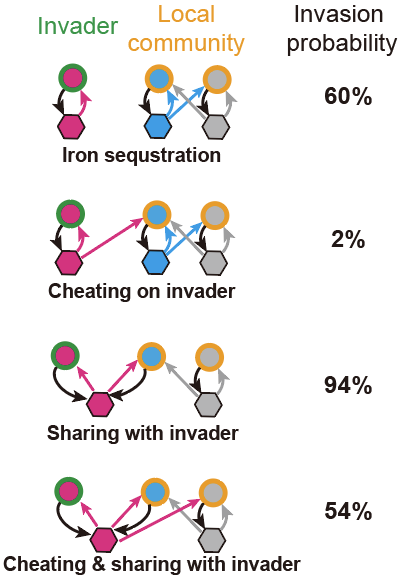

**Function to simulate community: simulation_community_interaction4**

function [t_values,m_values,g_values,j_values,Rcom_values,Rsid_values,Riron_values,dmdt]...
    = simulation_community_interaction4(num_strain,num_sid,a,m0,Riron_supply,t_end,h,barcode_syn,barcode_rec)
% a general function to simulate the dynamics of a community
% interaction based on bar code
% change ep k1 k2 to alternate the steady state sid value
% alternate the step size
% from simulation_community_interaction3_tune.m
% reduce the memory usage

arguments
    num_strain = 2 % number of strains
    num_sid = 2 % number of sid
    a = 0.5*ones(2,num_strain) % strategies of strains
    m0=ones(1,num_strain) % initial mass of strains
    Riron_supply=1 % iron supplied
    t_end=200 % simulation range
    h = 0.05 % step size
    barcode_syn=[1,0;...
            0,1]
    barcode_rec=[1,0;...
            0,1]
end

t0 = 0;             % Initial time
d = 0.01;            % dilution rate
vm = 0.1;             % rate cofficient for complex influxes
Km = 1;             % affinity cofficient
k1 = 1e-2;           % iron-sid association
k2 = 1e-7;             % iron-sid dissociation
gm = 20;            % growth coefficient: gamma
ep = 0.2;             % production coefficient: epsilon
r = 1;              % biomass per cell volume

% Initialize arrays to store the results
t_values = (t0:h:t_end).';
t_record = (t0:t_end).';
t_record_index = 0;
m_values = zeros(size(t_record,1)-1,num_strain); % biomass, each column: one strain
g_values = zeros(size(t_record,1)-1,num_strain); % growth rate
j_values = zeros(size(t_record,1)-1,num_strain);          % fluxes of sid
Rcom_values = zeros(size(t_record,1)-1,num_sid); % complex
Rsid_values = zeros(size(t_record,1)-1,num_sid); % siderophore
Riron_values = zeros(size(t_record,1)-1,1);      % iron

m_values(1,:) = m0;
Riron_values(1) = Riron_supply;

m = m_values(1,:); % biomass, each column: one strain
g = g_values(1,:); % growth rate
j = j_values(1,:);          % fluxes of sid
Rcom = Rcom_values(1,:); % complex
Rsid = Rsid_values(1,:); % siderophore
Riron = Riron_values(1,:);      % iron

for i = 1:length(t_values) - 1

%     if i == 458
%         qzy=1
%     end

    % iterate biomass m
    j = vm.*Rcom*barcode_rec; % fluxes of sid
    g = gm.*a(1,:).*j; % growth rate
    
    dmdt = m.*(g-d).*h;
    m = m + dmdt;

    % iterate siderophore Rsid
    dRsid_dt = (- d.*Rsid + ep.*a(2,:).*m*(barcode_syn.')./r ...
        - k1.*Riron.*Rsid + k2.*Rcom) .*h;
    Rsid = Rsid + dRsid_dt;
    

    % iterate complex Rcom
    dRcom_dt = (- d.*Rcom - m./r.*vm*(barcode_rec.').*Rcom ...
        + k1.*Rsid.*Riron - k2.*Rcom).*h;
    Rcom = Rcom + dRcom_dt;
    

    % iterate iron Riron
    dRiron_dt = (d*(Riron_supply-Riron) ...
        +sum(-k1*Rsid*Riron + k2*Rcom,2)).*h;
    Riron = Riron + dRiron_dt;
    

    if any(Rcom<0)
        qzy =1
    end

    if t_values(i)>=t_record(t_record_index+1)
        j_values(t_record(t_record_index+1)+1,:) = j;
        g_values(t_record(t_record_index+1)+1,:) = g;
        m_values(t_record(t_record_index+1)+1,:) = m;
        Rsid_values(t_record(t_record_index+1)+1,:) = Rsid;
        Rcom_values(t_record(t_record_index+1)+1,:) = Rcom;
        Riron_values(t_record(t_record_index+1)+1) = Riron;
        t_record_index = t_record_index+1;
    end

end

end

**Function to simulate an invasion event within a community: simulation_community_interaction4_breakpoint.m**

function [t_values,m_values,g_values,j_values,Rcom_values,Rsid_values,Riron_values,dmdt]...
    = simulation_community_interaction4_breakpoint(num_strain,num_sid,a,m0,Riron_supply,t_end,h,barcode_syn,barcode_rec,g0,j0,Rcom0,Rsid0,Riron0)
% a general function to simulate the dynamics of a community
% interaction based on bar code
% change ep k1 k2 to alternate the steady state sid value
% alternate the step size
% from simulation_community_interaction4.m
% reduce the memory usage

arguments
    num_strain = 2 % number of strains
    num_sid = 2 % number of sid
    a = 0.5*ones(2,num_strain) % strategies of strains
    m0=ones(1,num_strain) % initial mass of strains
    Riron_supply=1 % iron supplied
    t_end=200 % simulation range
    h = 0.05 % step size
    barcode_syn=[1,0;...
            0,1]
    barcode_rec=[1,0;...
            0,1]
    g0=0 % initial value for growth rate
    j0=0 % initial value for Rcom import rate
    Rcom0=0 % initial value for Rcom
    Rsid0=0 % initial value for Rsid
    Riron0=Riron_supply % initial value for Riron
end

t0 = 0;             % Initial time
d = 0.01;            % dilution rate
vm = 0.1;             % rate cofficient for complex influxes
Km = 1;             % affinity cofficient
k1 = 1e-2;           % iron-sid association
k2 = 1e-7;             % iron-sid dissociation
gm = 20;            % growth coefficient: gamma
ep = 0.2;             % production coefficient: epsilon
r = 1;              % biomass per cell volume

% Initialize arrays to store the results
t_values = (t0:h:t_end).';
t_record = (t0:t_end).';
t_record_index = 0;
m_values = zeros(size(t_record,1)-1,num_strain); % biomass, each column: one strain
g_values = zeros(size(t_record,1)-1,num_strain); % growth rate
j_values = zeros(size(t_record,1)-1,num_strain);          % fluxes of sid
Rcom_values = zeros(size(t_record,1)-1,num_sid); % complex
Rsid_values = zeros(size(t_record,1)-1,num_sid); % siderophore
Riron_values = zeros(size(t_record,1)-1,1);      % iron

m_values(1,:) = m0;
g_values(1,:) = g0;
j_values(1,:) = j0;
Rcom_values(1,:) = Rcom0;
Rsid_values(1,:) = Rsid0;
Riron_values(1) = Riron0;

m = m_values(1,:); % biomass, each column: one strain
g = g_values(1,:); % growth rate
j = j_values(1,:);          % fluxes of sid
Rcom = Rcom_values(1,:); % complex
Rsid = Rsid_values(1,:); % siderophore
Riron = Riron_values(1,:);      % iron

for i = 1:length(t_values) - 1

%     if i == 458
%         qzy=1
%     end

    % iterate biomass m
    j = vm.*Rcom*barcode_rec; % fluxes of sid
    g = gm.*a(1,:).*j; % growth rate
    
    dmdt = m.*(g-d).*h;
    m = m + dmdt;

    % iterate siderophore Rsid
    dRsid_dt = (- d.*Rsid + ep.*a(2,:).*m*(barcode_syn.')./r ...
        - k1.*Riron.*Rsid + k2.*Rcom) .*h;
    Rsid = Rsid + dRsid_dt;
    

    % iterate complex Rcom
    dRcom_dt = (- d.*Rcom - m./r.*vm*(barcode_rec.').*Rcom ...
        + k1.*Rsid.*Riron - k2.*Rcom).*h;
    Rcom = Rcom + dRcom_dt;
    

    % iterate iron Riron
    dRiron_dt = (d*(Riron_supply-Riron) ...
        +sum(-k1*Rsid*Riron + k2*Rcom,2)).*h;
    Riron = Riron + dRiron_dt;
    

    if any(Rcom<0)
        qzy =1
    end

    if t_values(i)>=t_record(t_record_index+1)
        j_values(t_record(t_record_index+1)+1,:) = j;
        g_values(t_record(t_record_index+1)+1,:) = g;
        m_values(t_record(t_record_index+1)+1,:) = m;
        Rsid_values(t_record(t_record_index+1)+1,:) = Rsid;
        Rcom_values(t_record(t_record_index+1)+1,:) = Rcom;
        Riron_values(t_record(t_record_index+1)+1) = Riron;
        t_record_index = t_record_index+1;
    end

end

end

**Function to generate community: generate_mix_invasion.m, generate_mix_invasion_2component.m**

function [barcode_syn,barcode_rec,a,m0,community_name]=generate_mix_invasion(k,num_strain,community,invader)

barcode_syn = [community.barcode_syn_record(:,1:num_strain-1,k) invader.barcode_syn_record(:,num_strain,k)];
barcode_rec = [community.barcode_rec_record(:,1:num_strain-1,k) invader.barcode_rec_record(:,num_strain,k)];
a = [community.a_record(k,1:num_strain-1) invader.a_record(k,num_strain)];
m0 = [community.m0_record(k,1:num_strain-1) invader.m0_record(k,num_strain)];
a = [a;1-a];
community_name=[inputname(4) '_invade_' inputname(3)];
end

function [barcode_syn,barcode_rec,a,m0,community_name,splitPoints]=generate_mix_invasion_2component(k,num_strain,community1,community2,invader)
rng(k)
splitPoints = sort(randperm(num_strain-2, 1));

barcode_syn = [community1.barcode_syn_record(:,1:splitPoints,k),...
               community2.barcode_syn_record(:,splitPoints+1:num_strain-1,k),...
               invader.barcode_syn_record(:,num_strain,k)];
barcode_rec = [community1.barcode_rec_record(:,1:splitPoints,k),...
               community2.barcode_rec_record(:,splitPoints+1:num_strain-1,k),...
               invader.barcode_rec_record(:,num_strain,k)];
a = [community1.a_record(k,1:splitPoints),...
     community2.a_record(k,splitPoints+1:num_strain-1),...
     invader.a_record(k,num_strain)];
m0 = [community1.m0_record(k,1:splitPoints),...
     community2.m0_record(k,splitPoints+1:num_strain-1),...
     invader.m0_record(k,num_strain)];
a = [a;1-a];
community_name=[inputname(5) '_invade_mix'];
end